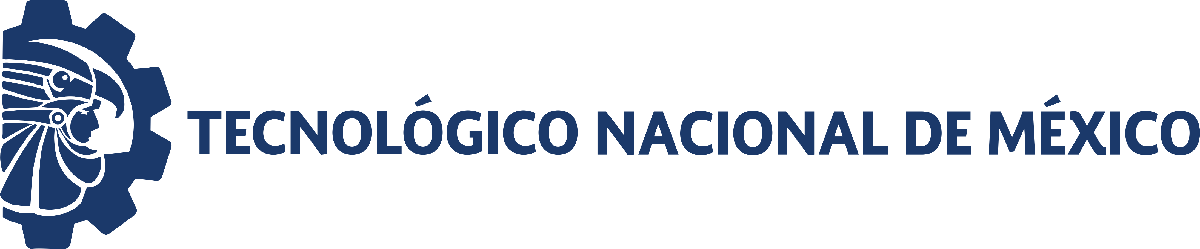                                 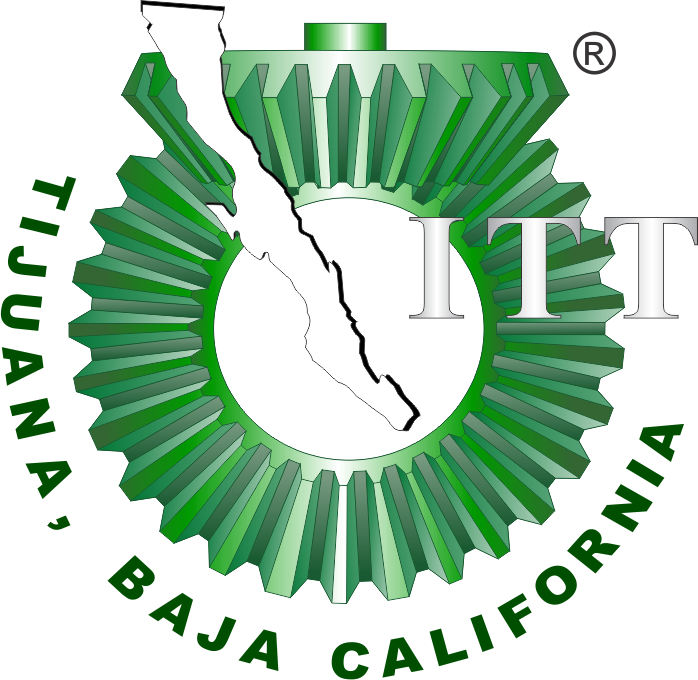

# Proyecto: Modelado de la sistema de la nefrona

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

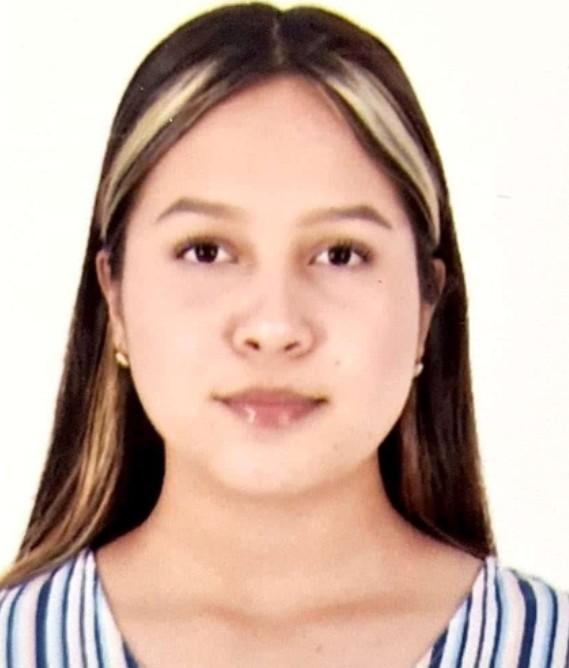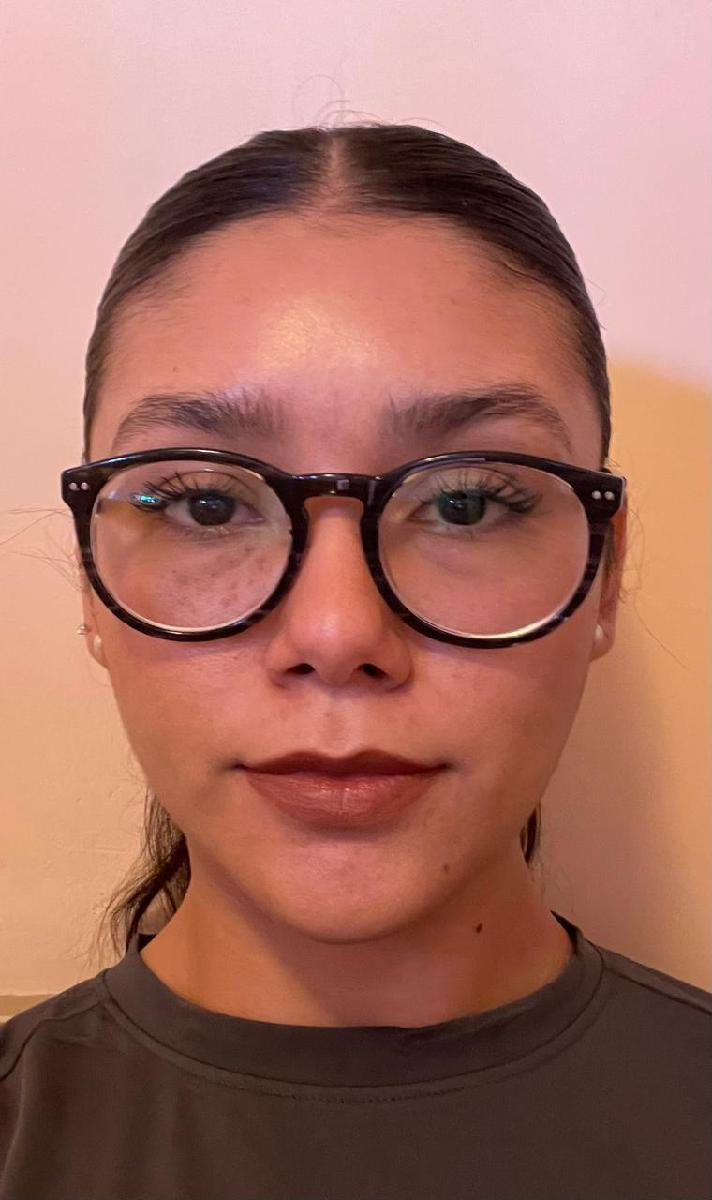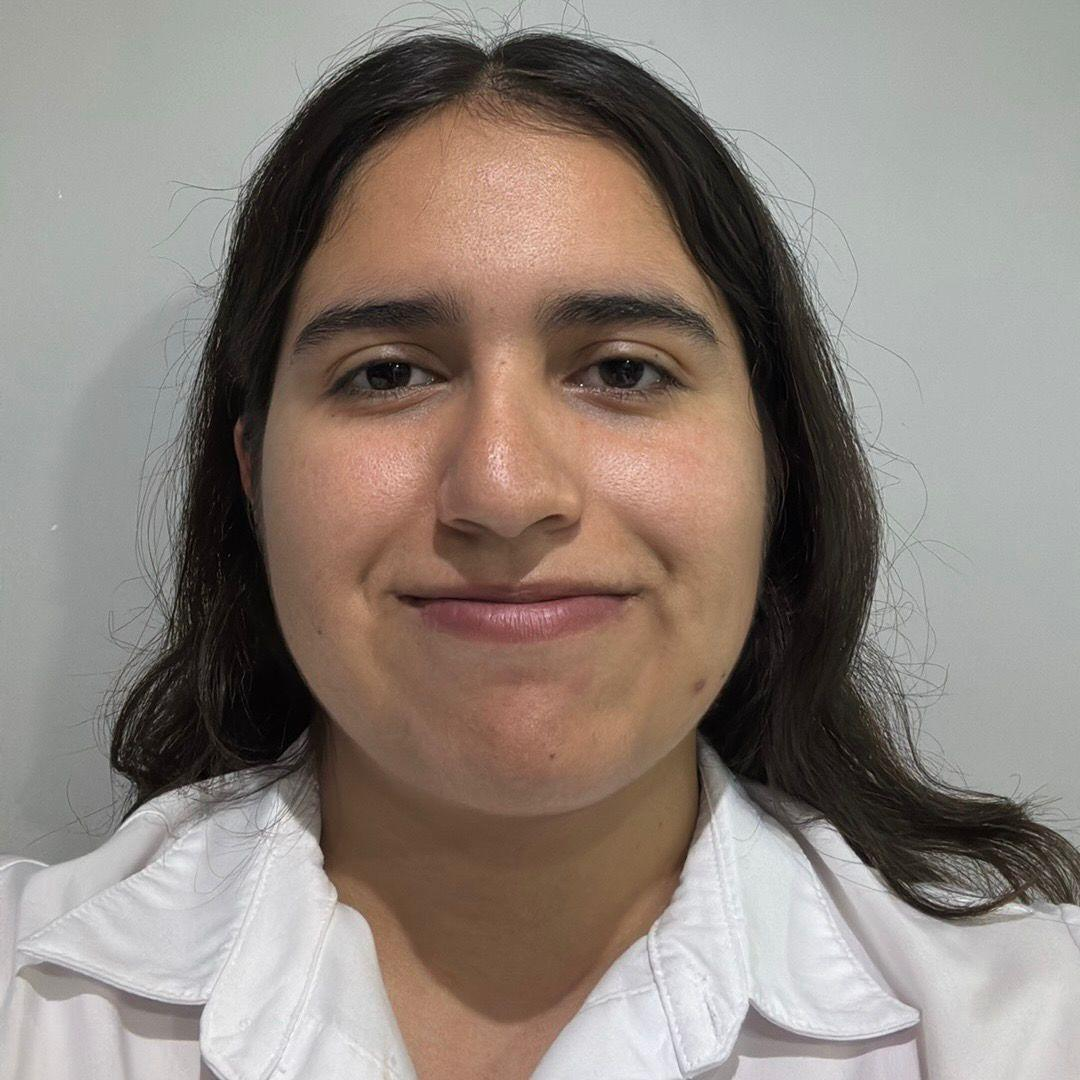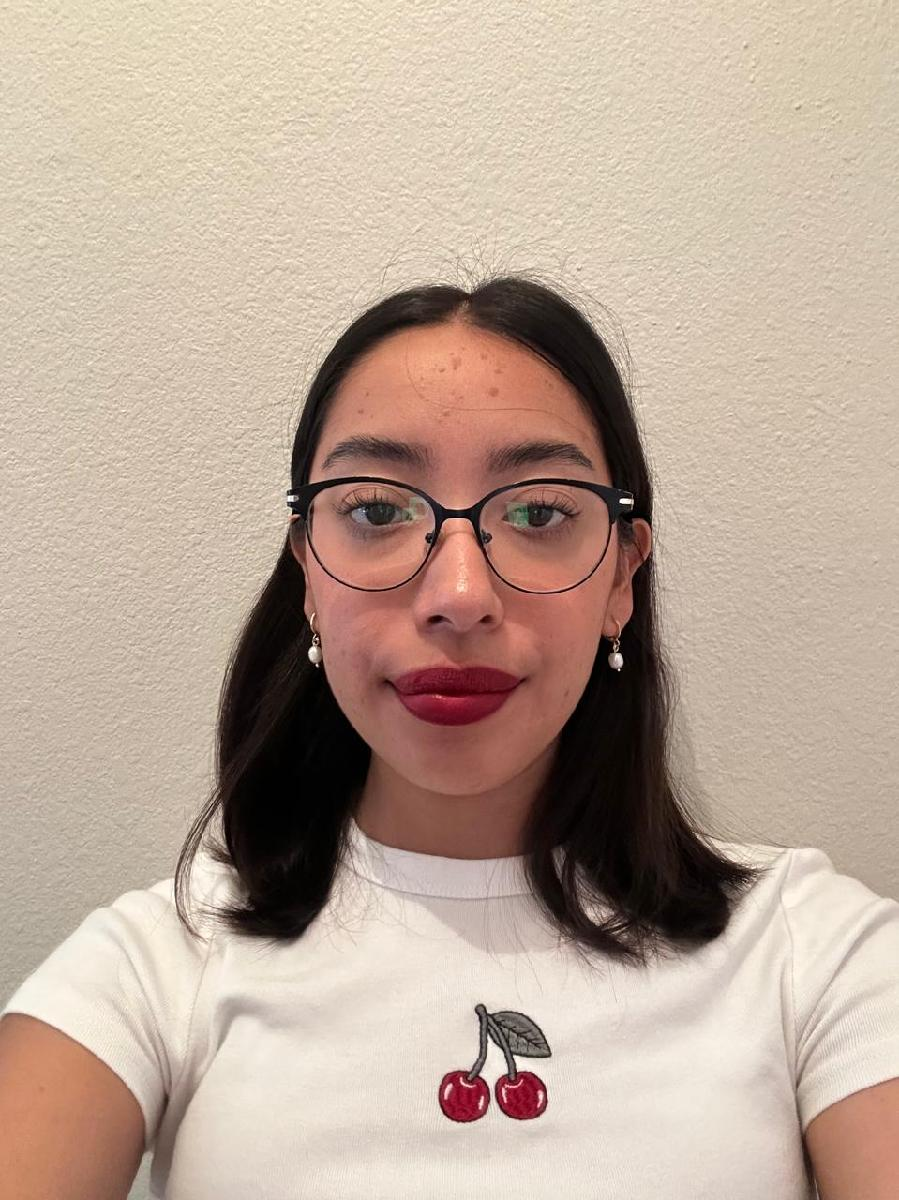

Nombre del alumno: **Durán Sofía, Galindo Belén, Sifuentes Anadali, Valle Ana**

Número de control: **22211752, 22211755, 22212273, 22211769**

Correo institucional:** l22211752@tectijuana.edu.mx, l22211755@tectijuana.edu.mx, l22212273@tectijuana.edu.mx, l22211769@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('sistema/Ve(t)', 'Time', '0');              
set_param('sistema/Ve(t)', 'Before', '0');           
set_param('sistema/Ve(t)', 'After', '120');           
set_param('sistema/Ve(t)', 'SampleTime', '0');

## Respuesta en lazo abierto

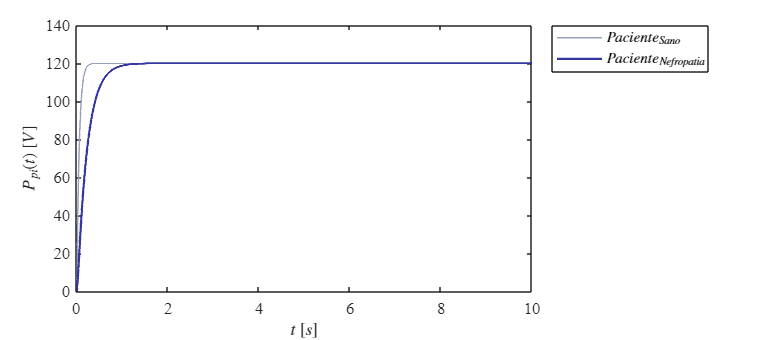

x1 = sim(file,parameters);
plotsignalsla(x1.t,x1.Vs1,x1.Vs2,'Señal');

## Respuesta en lazo cerrado

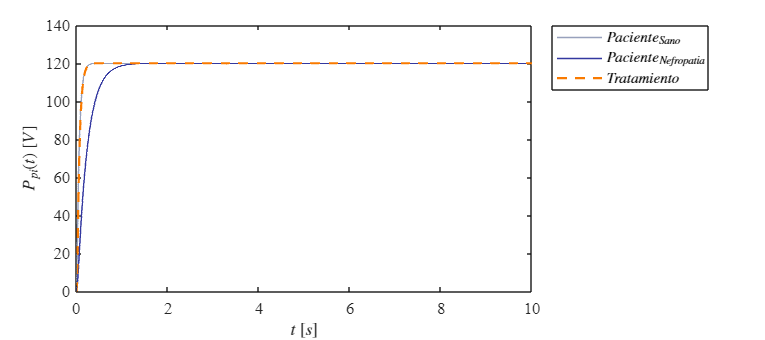

x2 = sim(file,parameters);
plotsignalslc(x2.t,x2.Vs1,x2.Vs2,x2.Vs3,'Señal');

## Funcion: Respuesta a las señales

function plotsignalslc(t,Vs1,Vs2,Vs3,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman', 'FontSize',11)
    hold on; grid off;box on;
    mycolors = [152,161,188;
        51,56,160;
        249,122,0]/255;
    colororder(mycolors)
   
    p = plot(t,Vs1,'-',t,Vs2,'-',t,Vs3,'--',...
        'LineWidth',1,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',1.5);
    L = legend('$Paciente_{Sano}$','$Paciente_{Nefropatia}$','$Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
    
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$P_{pi}(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    
    xlim([0,10]);xticks(0:2:10);
    ylim([0,140]);yticks(0:20:140);
    
    exportgraphics(gcf,[Signal,'_lazoCerrado.pdf'], 'ContentType','vector')
    exportgraphics(gcf,[Signal,'_lazoCerrado.png'], 'Resolution',300)
end

function plotsignalsla(t,Vs1,Vs2,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman', 'FontSize',11)
    hold on; grid off;box on;
    mycolors = [152,161,188;
        51,56,160;
        249,122,0]/255;
    colororder(mycolors)
   
    p = plot(t,Vs1,'-',t,Vs2,'-',...
        'LineWidth',1,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(2),'LineWidth',1.5);
    L = legend('$Paciente_{Sano}$','$Paciente_{Nefropatia}$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
    
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$P_{pi}(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]);xticks(0:2:10);
    ylim([0,140]);yticks(0:20:140);
    
    exportgraphics(gcf,[Signal,'_lazoAbierto.pdf'], 'ContentType','vector')
    exportgraphics(gcf,[Signal,'_lazoAbierto.png'], 'Resolution',300)
end